# Filter Design: Zero-pole placement technique

#### by Rodolfo Muñoz

## 1) Zero cancellation

Let $x$ be the input of the system, where $x$ is given by:


$$x[n]= 2cos(0.1n) + cos(0.4n)$$


And we want to filter the low frequency component using a system$y$ that has an **impulse response** of:

$h[0] = h[2] = \alpha_0  $ ,  $h[1] = \alpha_1$

Then, the frequency response $H(z)$ is given by:

  
$$a_0 + a_1z^{-1} + a_0z^{-2}$$


As such, it is a system with zeros at the roots of the previous polynomial. To erase the low frequency component, we need to make the **zeros equal to the point of the unit circle with frequency **$w_1$of the undesired component. Then:


$$H_{zero} = \frac{-a_1 \pm \sqrt{a_1^2 - 4a_a^2}}{2a_0} = e^{jw_1}$$


$\Longrightarrow$$\frac{-a_1}{2a_0} = cos(w_1)$  *(real component)*


$$a_1 = -2a_0cos(w_1)$$


With that, we define the filter and use it to erase the low frequency component of $x$

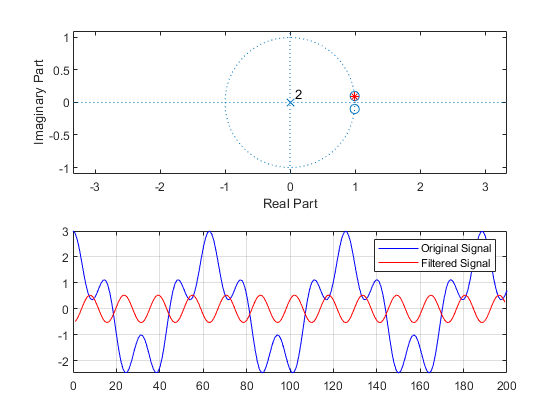

n = 0:200;
w_1 = 0.1;
w_2 = 0.4;
x = 2*cos(w_1*n) + cos(w_2*n);

a_0 = 3.6;
a_1 = -2*a_0*cos(w_1);
h = [a_0 a_1 a_0];
y = conv(x,h,'same');

figure('name','Signal Filtering')
subplot(2,1,1)
zplane(h,1); hold on;
plot(cos(w_1),sin(w_1),'r*'); hold off;
subplot(2,1,2)
plot(n,x,'b'); hold on;
plot(n(2:end-1),y(2:end-1),'r'); hold off;
axis tight, grid on;
legend({'Original Signal','Filtered Signal'})

## 2) IIR Filter Design

The objective is to design a 2nd order filter with the following requeriments:

- Magnitude response of $0$ at $w_1 =0$ and $w_3 =\pi \;$ 

- Maximum magnitude of $1$ at $w_{2,4} =\pm \frac{\pi }{4}$

- Magnitude response of approximately $\frac{1}{\sqrt{2}}$  at $w_{2,4} \pm 0\ldotp 05$

Then, we define the frequency points of the filter:

clear variables, close all;
w1 = 0; 
w2 = pi/4;  w4 = -w2;
w3 = pi;
thresh = 0.05;

By the requeriments, the filter must have the form


$$H(z) = \frac{b_0 + b_1z^{-1} + b_2z^{-2}}{a_0 + a_1z^{-1} + a_2z^{-2}} = K\frac{(z-z_1)(z-z_2)}{(z-p_1)(z-p_2)}$$
 

where $w_{1,3}$ are the zeros of the numerator $z_{1,2}$. And the frequencies $w_{2,4}$ define at which angle the poles $p_{1,2}$ must be in the Z Plane, as the points from the unit circle closest to them will be the ones with the maximum magnitude. Then:

$H(z) = K\frac{(z-e^{j\omega_1})(z-e^{j\omega_3})}{(z-re^{j\omega_2})(z-re^{j\omega_4})}$, $0<r<1$

b = poly([exp(1i*w1) exp(1i*w3)]);  % recovers polynomial coeff based on its roots

To get the parameters $K$and $r$, we can do a minimization with the 3rd requirement for the filter...


$$\left|H\left(w_{2,4} \pm 0\ldotp 05\right)\right|\approx \frac{1}{\sqrt{2}}\;\left|H\left(w_{2,4} \right)\right|$$


For that we'll use the Levenberg-Marquardt algorithm, so the result can be obtained with:

r0 = 0.99;     % initial guess for the value of r
optim_ops = optimset('Algorithm','levenberg-marquardt');
r = lsqnonlin(@(x) errorR(b,w2,x,thresh),r0,[],[],optim_ops); % function that minimizes error with the 3rd requirement


Local minimum possible.
lsqnonlin stopped because the relative size of the current step is less than
the value of the step size tolerance.

<stopping criteria details>


a = poly(r*[exp(1i*w2) exp(1i*w4)]);

Now, we only need to find the peak value at $w_{2,4}$ and divide everything by it to set the maximum of $H\left(z\right)$ to 1 

MAX = abs(polyval(b,exp(1i*w2)))/abs(polyval(a,exp(1i*w2)));
b = b/MAX;

We can check the results with the following graphs:

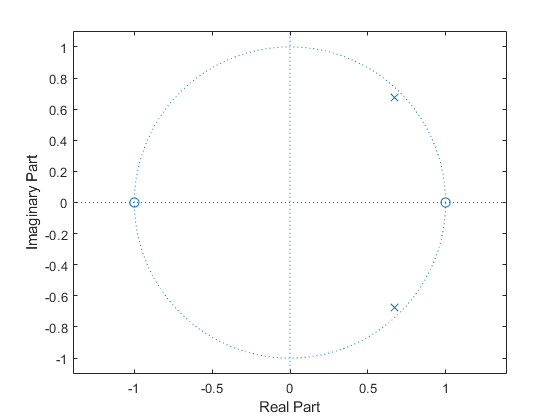

n = 0:150;
x1 = sin(w2*n);
x2 = sin((w2+thresh)*n);
y1 = filter(b,a,x1); y1 = real(y1);
y2 = filter(b,a,x2); y2 = real(y2);

zplane(b,a)

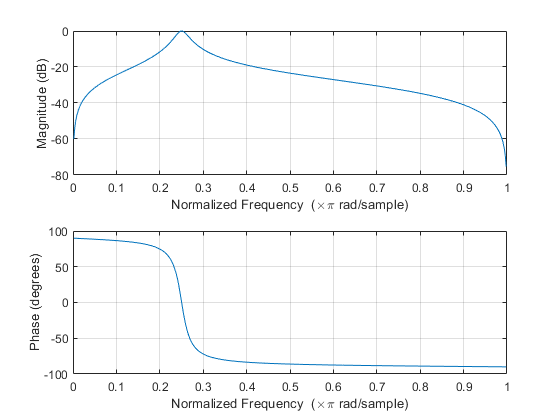

freqz(b,a)

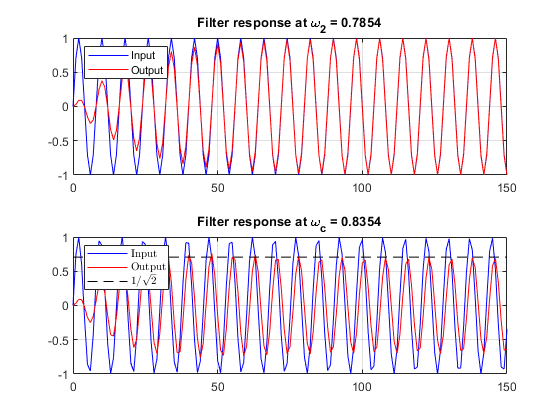


figure('name','System Response')
subplot(2,1,1)
plot(n,x1,'b'); hold on;
plot(n,y1,'r'); 
legend({'Input','Output'},'Location',"northwest");
title(['Filter response at \omega_2 = ' num2str(w2)])
grid on, hold off;
subplot(2,1,2)
plot(n,x2,'b'); hold on;
plot(n,y2,'r');
line([min(n) max(n)],[1/sqrt(2) 1/sqrt(2)],'Color','k','LineStyle','--')
legend({'Input','Output','$1/\sqrt{2}$'},'Interpreter','latex','Location',"northwest");
title(['Filter response at \omega_c = ' num2str(w2+thresh)])
grid on, hold off;

## 3) Compensating the effect of a Sample and Hold in a Digital-to-Analog-Converter (DAC)

The DAC measures the analog signal at specific intervals $T_s$, and records the value sampled as a constant for the whole period. 

clear variables, close all;
L = 256;
n = 0:120;
w_n = 0.15;
x = sin(w_n*pi*n)+2*sin(w_n*0.5*pi*n);

Then we can simulate the effect of the DAC like this:

Ts = 5;
window = [zeros(1,Ts) ones(1,Ts)];
x_s = zeros(1,length(x));
x_s(1:Ts:end) = x(1:Ts:end);
x_dac = conv(x_s,window,'same');

Which can be seen here, along its DFT:

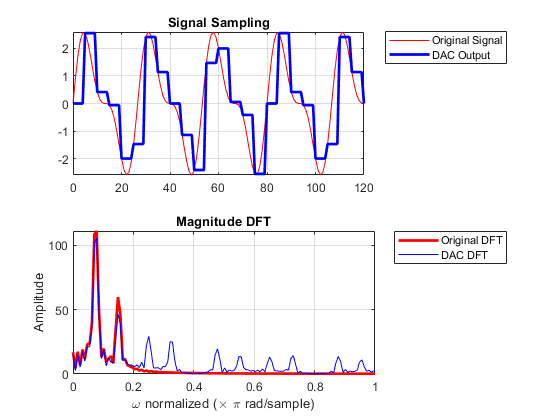

X = fft(x,L);
X_s = fft(x_s,L);
X_dac = fft(x_dac,L);
w = (0:L-1)/(L-1)*2;
mag = (abs(X));
mag_dac = (abs(X_dac));
phase = unwrap(angle(X));
phase_dac = unwrap(angle(X_dac));

subplot(2,1,1)
plot(n,x,'r'); hold on;
plot(n,x_dac,'b','LineWidth',2); 
grid on, hold off;
legend({'Original Signal','DAC Output'},'Location',"northeastoutside")
title('Signal Sampling');

subplot(2,1,2)
plot(w,mag,'r','LineWidth',2); hold on;
plot(w,mag_dac,'b'); 
grid on, hold off;
axis([0 1 0 max(abs(X))])
xlabel('\omega normalized (\times \pi rad/sample)');
ylabel('Amplitude')
legend({'Original DFT','DAC DFT'},'Location',"northeastoutside")
title('Magnitude DFT');

As seen in the graph, the sample and hold **adds harmonics** to the the original signal. 

If we look at the **DAC signa**l like we didn't knew the original beforehand, it looks like a **waveform** that originates from at least **2 main frequencies**. And in the DFT graph, we can see 2 major peaks at frequencies lower than 0.2 rad/sample and a pattern were those 2 peaks are repeated over and over, like harmonics. 

Then, we design a **Low Pass Filter** using the **zeros/poles technique** to filter all the harmonics, that is, we put zeros around the frequencies of the harmonics and poles near the frequencies we want to preserve.

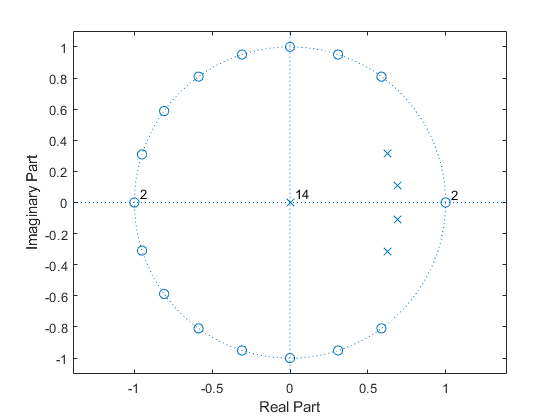

wn_zeros = pi*[0 0.3 0.4 0.5 0.6 0.7 0.8 0.9 1];
wn_poles = pi*[0.05 0.15];
r = 0.7;
b = -poly(exp(1i*[wn_zeros -wn_zeros]));
a = poly(r*exp(1i*[wn_poles -wn_poles]));

figure;
zplane(b,a)

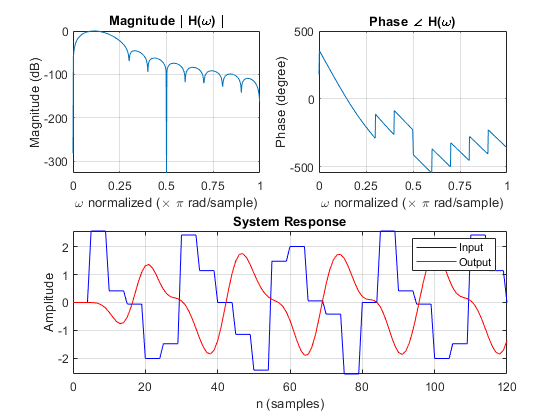

[LPF,] = freqz(b,a);
b = b/max(abs(LPF));
[~,~,y] =  filterresponse(b,a,x_dac,'magplot','indb');

With that, recovered the signal looks similar to the original before the DAC sampling. If we plot both signals we can see that the original waveform is indeed recovered with the filter, although with a different amplitude, because the Low Pass Filter didn't have a flat response at the passband:

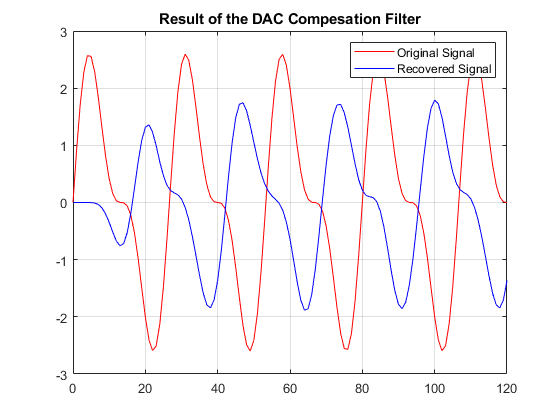

figure;
plot(n,x,'r'); hold on;
plot(n,y,'b'); 
grid on, hold off;
legend({'Original Signal','Recovered Signal'})
title('Result of the DAC Compesation Filter')